clear all
close all
clc

l1 = 6;
l2 = 7;
l3 = 3;
l4 = 2;

q1 = 0;
q2 = 0;

R(1) = Link('revolute','d',l1,'alpha',pi/2,'a',l3,'offset',pi/2);
R(2) = Link('prismatic','theta',0,'alpha',0,'a',0,'offset',l2+l4);
R(2).qlim = [0,10];

Robot = SerialLink(R,'name','Bender')

 
Robot = 
 
Bender (2 axis, RP, stdDH, fastRNE)                              
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          6|          3|      1.571|      1.571|
|  2|          0|         q2|          0|          0|          9|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


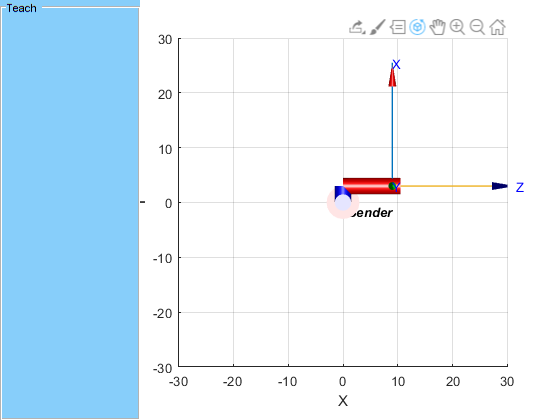

Error using SerialLink/plot>plot_options (line 711)
Prismatic joint(s) present: requires the 'workspace' option

Error in SerialLink/plot (line 207)
    opt = plot_options(robot, varargin);

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('SerialLink/teach', 'C:\Users\diego\Documents\MATLAB\rvctools\robot\@SerialLink\teach.m', 168)" style="font-w


Robot.plot([q1,q2],'scale',1.0,'workspace',[-30 30 -30 30 -30 30]);
zlim([-15,30]);
Robot.teach([q1,q2],'rpy/zyx');

MTH = Robot.fkine([q1,q2])

%Matriz (DH)
TZ0 = [1 0 0 0; 0 1 0 0; 0 0 1 l1; 0 0 0 1]
RZ0 = [cos(q1+pi/2) -sin(q1+pi/2) 0 0; sin(q1+pi/2) cos(q1+pi/2) 0 0; 0 0 1 0; 0 0 0 1]
TX1 = [1 0 0 l3; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RX1 = [1 0 0 0; 0 cos(pi/2) -sin(pi/2) 0; 0 sin(pi/2) cos(+pi/2) 0; 0 0 0 1]
T01 =  TZ0*RZ0*TX1*RX1
T01 =  RZ0*TZ0*RX1*TX1

TZ1 = [1 0 0 0; 0 1 0 0; 0 0 1 q2+l2+l4; 0 0 0 1]
RZ1 = [cos(0) -sin(0) 0 0; sin(0) cos(0) 0 0; 0 0 1 0; 0 0 0 1]
TX2 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RX2 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]
T12 =  TZ1*RZ1*TX2*RX2
T12 =  RZ1*TZ1*RX2*TX2

T02 = T01*T12

%Confirmar la rotación en ángulos de Euler
m = T02(1:3,1:3)
r = rad2deg(tr2rpy(m,'zyx'))